XTrain = num2cell(y_train(1:end-1));
YTrain = num2cell(y_train(2:end));

XTest = num2cell(y_test(1:end-1));
YTest = num2cell(y_test(2:end));


net1 = net;
net1 = predictAndUpdateState(net1,XTrain);
q = YTest(end);
[net1,YPred] = predictAndUpdateState(net1,q);

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

FNN

addpath('data', 'linearRegression', 'preprocessing');
addpath('plotting');
T = readtable('GOOGL_2006-01-01_to_2018-01-01.csv');
%T = readtable('AABA_2006-01-01_to_2018-01-01.csv');


y1 = T{1:end,5};
%y1 = y1(2:end) - y1(1:end-1);

options = optimset('MaxIter', 500, 'Display', 'off' );
lambda = 2;     %2
input_layer_size = 20;  %20
hidden_layer_size = 20; %20
num_labels = 1;


q = max(abs(y1));

n_previous_days = input_layer_size;
[y, mx_y] = featureNormalizeZeroOne(y1, q);
[X,y] = timeSeriesFeatures(y,n_previous_days);

Split

[X_test, m_train, X_cv, m_cv, X_train, y_cv, y_train, m_test, y_test] = splitData(X, y, 0.6, 0.2);

/

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);
% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];


/

costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X_train, y_train, lambda);

[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 2.731542e-03
Iteration     2 | Cost: 2.638823e-03
Iteration     3 | Cost: 2.630807e-03
Iteration     4 | Cost: 2.615412e-03
Iteration     5 | Cost: 2.345100e-03
Iteration     6 | Cost: 2.239198e-03
Iteration     7 | Cost: 2.234806e-03
Iteration     8 | Cost: 2.230949e-03
Iteration     9 | Cost: 2.211424e-03
Iteration    10 | Cost: 2.207629e-03
Iteration    11 | Cost: 2.187491e-03
Iteration    12 | Cost: 2.182892e-03
Iteration    13 | Cost: 1.917477e-03
Iteration    14 | Cost: 1.651406e-03
Iteration    15 | Cost: 1.480434e-03
Iteration    17 | Cost: 1.471623e-03
Iteration    18 | Cost: 1.350685e-03
Iteration    19 | Cost: 1.032811e-03
Iteration    20 | Cost: 9.309329e-04
Iteration    21 | Cost: 9.261424e-04


/

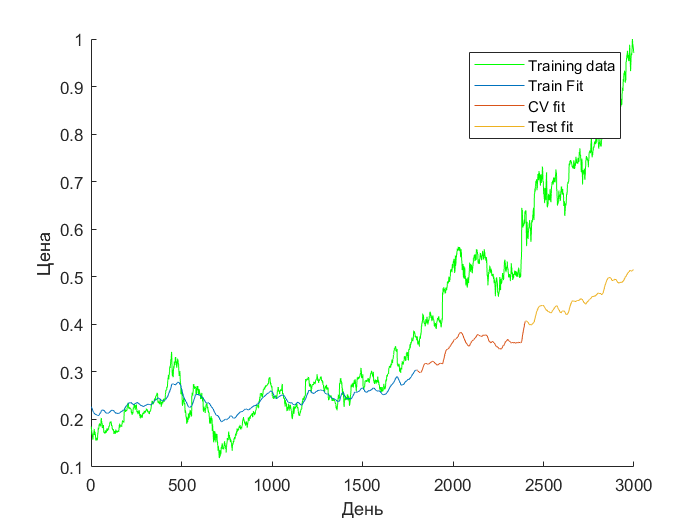

Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                 hidden_layer_size, (input_layer_size + 1));

Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                 num_labels, (hidden_layer_size + 1));
             
h1 = sigmoid([ones(size(X_train,1), 1) X_train] * Theta1');
hyp_train = sigmoid([ones(size(h1,1),1) h1] * Theta2');
                 
h1 = sigmoid([ones(size(X_cv,1), 1) X_cv] * Theta1');
hyp_cv = sigmoid([ones(size(h1,1),1) h1] * Theta2');

                 
h1 = sigmoid([ones(size(X_test,1), 1) X_test] * Theta1');
hyp_test = sigmoid([ones(size(h1,1),1) h1] * Theta2');

plotData(1:size(y,1),y,'День', 'Цена');
hold on; % keep previous plot visible
plot(m_train(1):m_train(2), hyp_train, '-')

plot(m_cv(1):m_cv(2),hyp_cv, '-');

plot(m_test(1):m_test(2),hyp_test, '-');

legend('Training data', 'Train Fit' , 'CV fit', 'Test fit')
hold off % don't overlay any more plots on this figure   


%predict x



addpath('data', 'linearRegression', 'preprocessing');
addpath('plotting');
T = readtable('GOOGL_2006-01-01_to_2018-01-01.csv');
%T = readtable('AABA_2006-01-01_to_2018-01-01.csv');


y1 = T{1:end,5};
%y1 = y1(2:end) - y1(1:end-1);

options = optimset('MaxIter', 500, 'Display', 'off' );
lambda = 0;     %2
input_layer_size = 10;  %20
hidden_layer_size = 10; %20
num_labels = 1;

n_previous_days = input_layer_size;
[y, mx_y] = featureNormalizeZeroOne(y1, max(y1)*2);
[X,y] = timeSeriesFeatures(y,n_previous_days);

Split

[X_test, m_train, X_cv, m_cv, X_train, y_cv, y_train, m_test, y_test] = splitData(X, y, 0.6, 0.2);

costFunction = @(p) nnCostFunction(p, input_layer_size, ...
    hidden_layer_size, num_labels, X_train, y_train, lambda)

costFunction = function_handle with value:
    @(p)nnCostFunction(p,input_layer_size,hidden_layer_size,num_labels,X_train,y_train,lambda)


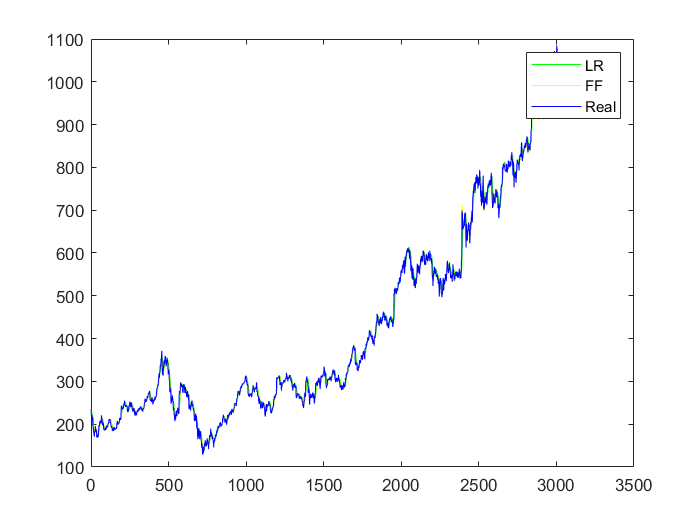

addpath('data', 'linearRegression', 'preprocessing');
addpath('plotting');
T = readtable('GOOGL_2006-01-01_to_2018-01-01.csv');
%T = readtable('AABA_2006-01-01_to_2018-01-01.csv');


y1 = T{10:end,5};

plot(hyp_LR, 'Color','g');
hold on;
%hyp_FNN2 = hyp_FNN*mx_y;
plot(hyp_FNN2, 'Color','y');
plot(y1, 'b');
legend('LR' ,'FF','Real')
hold off;